## Second Laboratory - Data Analysis

### Development of perovskite solar cells using numerical computational software

Yeraldin Velez Galvis

yeraldinvelez236975@correo.itm.edu.co

#### *Abstract:*

In recent years, the urgency to adopt renewable energy sources has increased significantly due to the rapid climate change our planet is experiencing, driven by the exponential growth in greenhouse gas emissions from the use of fossil fuels. This need has become a major global concern, as it seeks to ensure a sustainable energy supply and reduce the environmental impact of fossil fuel-based technologies.

As a result, the development, optimization and improvement of renewable energy generation systems have become key challenges for the scientific community. Solar energy, in particular, has experienced remarkable growth in this context. However, the most common commercial solar panels (such as monocrystalline or polycrystalline silicon panels) fail to capture much of the solar energy and achieve an energy efficiency between 15% and 20%, which means that a significant part of the solar energy is not fully harnessed. In addition, these panels have design limitations due to their mechanical rigidity and high weight. 

In contrast, perovskite solar cells have attracted considerable interest in recent years due to their remarkable increase in energy efficiency. Reaching 26.1% in commercial prototypes and a maximum of 37.5% in laboratory tests, these cells promise to be potential candidates for commercial production of the next generation of solar cells. Their adoption could significantly reduce electricity costs and simplify manufacturing processes. Hence, being able to generate computational methodologies that allow modeling, optimizing and predicting the optoelectronic characteristics of these cells is key to reducing the costs of this technology, especially considering that manufacturing techniques sometimes require the use of expensive reagents and clean rooms. It is then when being able to optimize the combination of materials and adjust the structural dimensions of the same from simulations plays a crucial role in driving the development of perovskite solar cells. In addition, the emergence of artificial intelligence techniques offers an innovative perspective in this field. These techniques can be effective in predicting the performance of solar cells, giving researchers a valuable tool to improve their efficiency and stability. This is especially important considering that the key parameters of these cells are critical to their performance. 

Therefore, this master work focuses on the development of a comprehensive computational methodology for the modeling of perovskite solar cells, making use of numerical modeling tools such as COMSOL Multiphysics and/or SCAPS 1D. The main objective is to understand and optimize the optoelectronic properties of these cells by analyzing various factors, such as the combination of materials, the number and order of layers, as well as the structural morphology. In addition, it is proposed to implement at least one tool based on machine learning techniques, aimed at predicting the behavior of perovskite solar cells. This will include the prediction of crucial parameters, such as energy conversion efficiency. It is expected that these tools will not only facilitate the design and optimization process, but also contribute to reducing the costs associated with the fabrication of these cells.

### Contextualization

Varying the layer thickness of perovskite solar cells is an important practice for optimizing their performance and efficiency. This technology can adjust several key aspects of a solar cell's performance, significantly affecting its ability to efficiently convert sunlight into electricity. First, by varying the thickness of the layer, we can control the amount of sunlight the cells can absorb. Because different layer thicknesses interact uniquely with incident light, this refinement optimizes photon absorption to maximize the amount of solar energy captured and converted into electricity. In addition, layer thickness also affects how quickly charges (such as electrons and holes) are transported through the cell. Optimal layer thickness promotes efficient charge transfer, reduces losses and increases the current generated by the cell. Another important aspect is the control of perovskite layer defects. Different thicknesses help control defect formation and density, thereby reducing losses and improving overall device quality. By reducing defects, the stability and durability of solar cells can be improved, which is very important for long-term use in solar cells. In summary, it is crucial to vary the layer thickness of perovskite solar cells to optimize their performance by adjusting the layer thickness.

### Description of data to be used

In the following lines of code a table is created for 3 different cells where the variation of their thicknesses from 50 nm to 1000 nm is performed. Three different electrical parameters such as open circuit voltage (Voc), short circuit current density (Jsc) and perovskite cell efficency (PCE) are loaded. Subsequently, the analysis of Voc, PCE and Jsc versus thickness will be made. 

1. (10%) Organize your data in a Pandas DataFrame, with well-defined column names. Each row must indicate a sample, and each column a feature, measurement of a variable, among others. The name of columns must be clear and straightforward to interpret. Make a visualization of the first rows of the DataFrame as a table.

*load:* The Matlab load command is used, which allows me to load into the workspace variables previously obtained by simulation using the COMSOL - Matlab connection. In this case, the variables that contain the range of thicknesses to be varied in the simulation are opened, the variables that contain the range of thicknesses to be varied in the simulation are opened. 

*table: *the table command allows you to concatenate data arrays in the form of a table, in this case the data has one column and 96 rows.  This dimension must be maintained to obtain the desired structure.

% The vectors obtained by simulation are loaded by varying the 
% thicknesses of the layers.
load('Jsc_Cell1.mat');
load('Jsc_Cell2.mat');
load('Jsc_Cell3.mat');
load('PCE_Cell1.mat');
load('PCE_Cell2.mat');
load('PCE_Cell3.mat');
load('Voc_Cell1.mat');
load('Voc_Cell2.mat');
load('Voc_Cell3.mat');
load('thickness_Cell1');


% The thickness variation of the three cells is the same, so thickness_Cell1 is used as a reference.
Thickness = thickness_Cell1; 

% The dataframe is created using the data of the electrical variables.
Solar_Cell = table(Thickness,Jsc_Cell1,Jsc_Cell2,Jsc_Cell3,Voc_Cell1,Voc_Cell2,Voc_Cell3,PCE_Cell1,PCE_Cell2,PCE_Cell3)

Solar_Cell = 96×10 table
    Thickness    Jsc_Cell1    Jsc_Cell2    Jsc_Cell3    Voc_Cell1    Voc_Cell2    Voc_Cell3    PCE_Cell1    PCE_Cell2    PCE_Cell3
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

        50         19.94       8.2195       16.853        1.13         1.18         1.12        12.564       6.0974       10.542  
        60        20.175        8.666       17.088        1.13         1.17         1.12        12.726       6.3872       10.694  
        70        20.408       9.1174       17.318        1.13         1.17         1.12        12.887       6

disp(Solar_Cell(1:5,:))

    Thickness    Jsc_Cell1    Jsc_Cell2    Jsc_Cell3    Voc_Cell1    Voc_Cell2    Voc_Cell3    PCE_Cell1    PCE_Cell2    PCE_Cell3
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

       50          19.94       8.2195       16.853        1.13         1.18         1.12        12.564       6.0974       10.542  
       60         20.175        8.666       17.088        1.13         1.17         1.12        12.726       6.3872       10.694  
       70         20.408       9.1174       17.318        1.13         1.17         1.12        12.887       6.6716       10.846  
    

2. (15%) Perform a statistical description of data, such as mean, interquartile ranges, standard deviation, mode, median, etc, of each column of the DataFrame. Use OOP instead of for loops unless necessary.

The mean of the DataFrame 'Solar_Cell' is calculated using POO by means of the Matlab command mean. 

The std command is also used to calculate the standard deviation of the electrical variables of the three cells.

disp('The mean of the electrical variables is: ')

The mean of the electrical variables is: 


Mean_Cells = mean(Solar_Cell)

Mean_Cells = 1×10 table
    Thickness    Jsc_Cell1    Jsc_Cell2    Jsc_Cell3    Voc_Cell1    Voc_Cell2    Voc_Cell3    PCE_Cell1    PCE_Cell2    PCE_Cell3
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

       525        25.045       30.514       21.965       1.1869       1.1259       1.1293       16.104       16.547       13.845  



disp('The standard deviation of the electrical variables is: ')

The standard deviation of the electrical variables is: 


Standard_Deviation_Cells = std(Solar_Cell)

Standard_Deviation_Cells = 1×10 table
    Thickness    Jsc_Cell1    Jsc_Cell2    Jsc_Cell3    Voc_Cell1    Voc_Cell2    Voc_Cell3    PCE_Cell1    PCE_Cell2    PCE_Cell3
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

     278.57       1.8035       13.074       1.8104      0.019046     0.013344     0.0033229     1.2449       5.3359       1.1552  


3. (20%) Explore separability of data using three kinds of plots. Analyze the results. 

4. (30%) Perform quantitative analysis of data separability using three different methods. Analyze the results. 

#### Mean of electrical variables

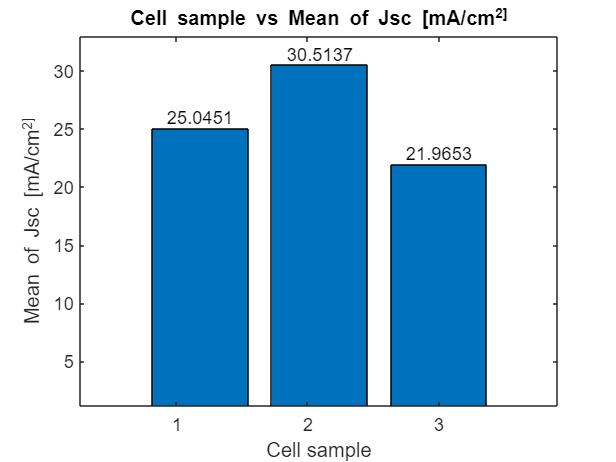

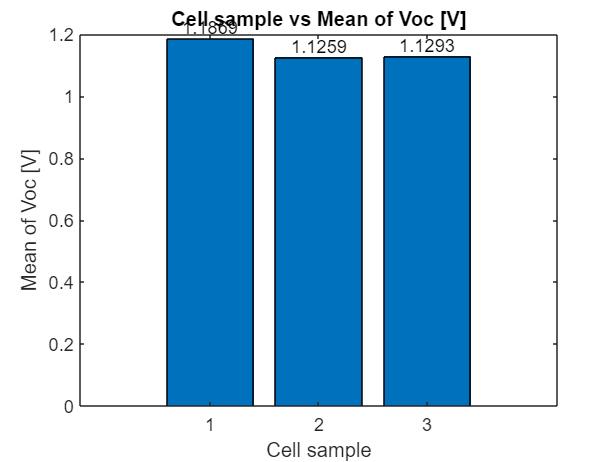

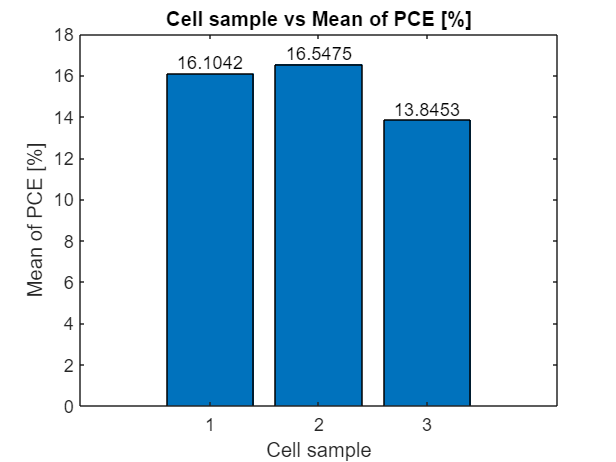


variables = {2:4, 5:7, 8:10};
labels = {'Jsc [mA/cm^2]', 'Voc [V]', 'PCE [%]'};
plot_means(Solar_Cell, variables, labels);

#### Analysis of separability using mean and bar plots

The average of the electrical variables allows an overall analysis of the performance of the cell and quantitatively determine which of them performs better, absorbs more energy and therefore generates the highest efficiency.

*Voc:* The average Voc for the three cells presents very similar values, this is because the voltage applied by simulation was from 0V to 1.2V and this value is not influenced by the materials or structure implemented, but by the range applied. In summary, evaluating the performance of perovskite solar cells is not very useful by analyzing the applied voltage through simulation.

*Jsc:* The current density presented values for the mean, where it is evident that the highest values were obtained for cell 2, which means that the cell was able to capture more sunlight and generate more current per unit area. It is important to analyze the average energy efficiency to confirm if the best performance is presented by cell 2.

*PCE: *Although the difference between the average of cell 1 and cell 2 is only 0.4%, it can be stated that among the 3 structures designed, cell 2 is the one with the best performance, not only because its efficiency is higher, but also because it achieves higher current values than the other two cells. This statistical analysis turns out to be very useful to evaluate which cell allows a better performance and, consequently, which thicknesses have a direct influence.

Energy efficiency is one of the most important performance parameters for solar cells, so in the previous code the average PCE is obtained for the 3 cells to be analyzed and it is observed that the cell with the highest average value was cell number 2. Additionally, it can be said that this cell presents better performance than the other two, which is of vital importance for the research being carried out.

#### Standard deviation for Jsc, Voc and PCE

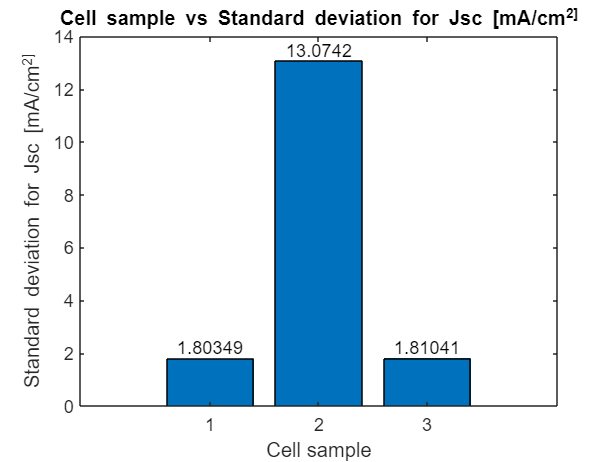

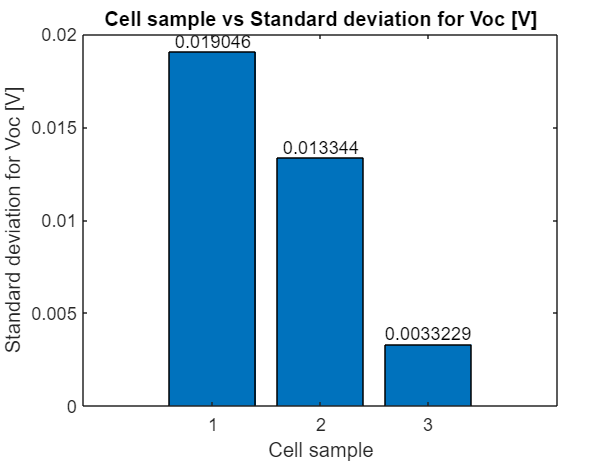

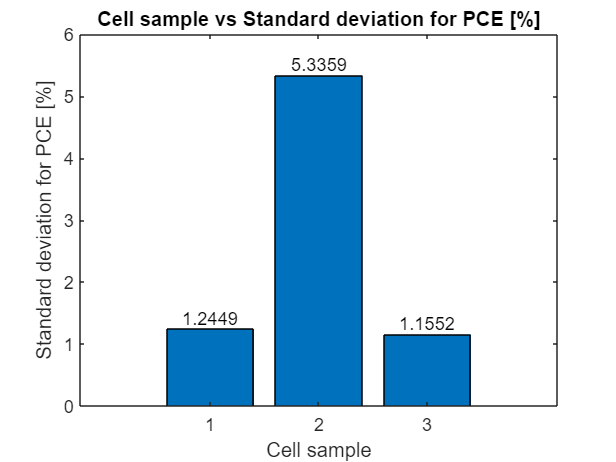


variables = {2:4, 5:7, 8:10};
labels = {'Jsc [mA/cm^2]', 'Voc [V]', 'PCE [%]'};
plot_standard_deviation(Solar_Cell, variables, labels);

#### Analysis of separability using standard deviation and bar plots

The standard deviation allows quantifying the dispersion of the data around the mean or the variability of the data. For the development of perovskite solar cells it is very useful to understand the variation of energy efficiency or current density with increasing thickness of the layers that compose the structure.

*Voc:* The standard deviation for Voc is very small, this is because the open circuit voltage values for the three cells change between 1.1V and 1.2V and confirming that the variation and dispersion of data is very small. This is because the applied voltage is the same for all three simulations. This is so because the results obtained by simulation, in experimental setups this does not occur, because the variations in sunlight due to the movement of the sun, increased surface temperature in the cell and losses due to cloudiness generate statistically significant variations between the different cells [4].

*Jsc:* The standard deviation for Jsc shows a very high value for cell 2, this indicates that the variation of thicknesses for the above mentioned cell generates an increase in current density with higher dispersion in the resulting values. This makes a lot of sense, as the current density for cell 2 increases significantly with increasing layer size, this measure proves to be very useful to evaluate which cell is more affected by the thickness variation. 

*PCE: *As in the graph for the standard deviation of Jsc, the deviation for PCE is noticeably higher in cell 2 compared to cells 1 and 3. This is because the maximum and minimum values of efficiency change strongly with increasing efficiency. It can be inferred from this result that cell 2 is more affected by the variation of thickness size and that a high value of standard deviation indicates that one cell may perform better than the others.

In conclusion, the analysis of the standard deviation using bar charts is very useful to determine the cell with the highest growth in energy efficiency.

#### Analysis of separability using mean and Box and Whisker Chart

The separability analysis using the box and whisker plot allows us to analyze the behavior of the data for each cell. 

For cell 1, it is observed that there are some outliers and that the energy efficiency only increases from 12% to 17% approximately, which indicates that the efficiency only increases by 5% when having a thickness from 50nm to 1000nm. 

For cell 2, the efficiency has an increase from 6% to approximately 25%, which represents an increase of 19% when varying the thickness. This indicates that the simulated design is sensitive to thickness changes and that its efficiency increases significantly with increasing layer size. 

Finally, cell 3 also shows an efficiency increase of only 4%, so it is not as susceptible to increase its efficiency when the cell thickness increases.

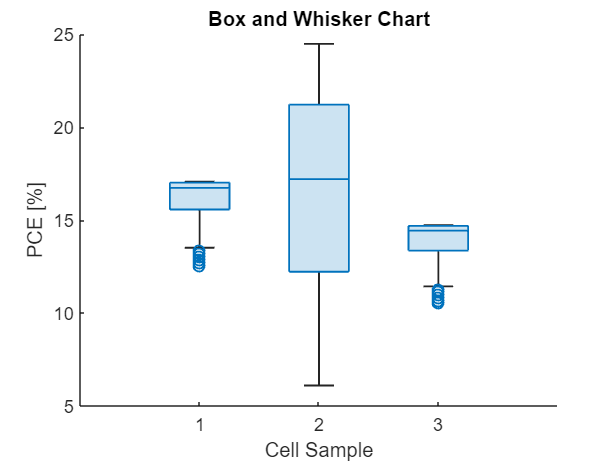

boxchart(table2array(Solar_Cell(:,8:10)))
xlabel('Cell Sample')
ylabel('PCE [%]')
title('Box and Whisker Chart')

#### Analysis of separability using mean and violin plot

A function available in the Matlab community [5] was used to perform separability analysis with violin plot. It allows to obtain the desired graph and to point out the mean and median in the graph. 

As in the box-and-whisker plot, cell 2 shows a more pronounced increase in energy efficiency for the thickness range between 50 nm and 1000 nm. From this it can be concluded again that cell 2 is more sensitive to thickness variation and performs better than cells 1 and 3.

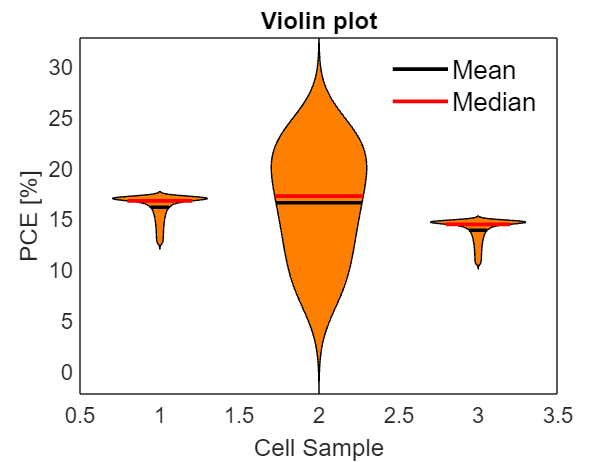

violin(table2array(Solar_Cell(:,8:10)));
xlabel('Cell Sample')
ylabel('PCE [%]')
title('Violin plot')

5. (5%) Make data normalization and compute again points 2, 3 and 4. Feel free to use any kind of data normalization. Compare and conclude.

The matlab normalize command is used, which allows the data to be normalized automatically without performing additional numerical calculations. 

% Normalized data
N = normalize(Solar_Cell);


#### Point 2 over normalized data

disp('The mean of normalized data: ')

The mean of normalized data: 


Mean_Cells = mean(N)

Mean_Cells = 1×10 table
    Thickness      Jsc_Cell1      Jsc_Cell2     Jsc_Cell3     Voc_Cell1      Voc_Cell2     Voc_Cell3      PCE_Cell1      PCE_Cell2     PCE_Cell3 
    __________    ___________    ___________    __________    __________    ___________    __________    ___________    ___________    __________

    6.9389e-18    -8.3267e-17    -8.7893e-17    1.5173e-15    1.5002e-14    -4.5262e-14    6.7404e-14    -2.0516e-15    -3.3307e-16    8.4655e-16



disp('The standard deviation of normalized data: ')

The standard deviation of normalized data: 


Standard_Deviation_Cells = std(N)

Standard_Deviation_Cells = 1×10 table
    Thickness    Jsc_Cell1    Jsc_Cell2    Jsc_Cell3    Voc_Cell1    Voc_Cell2    Voc_Cell3    PCE_Cell1    PCE_Cell2    PCE_Cell3
    _________    _________    _________    _________    _________    _________    _________    _________    _________    _________

        1            1            1            1            1            1            1            1            1            1    


Applying the mean on normalized data from a table may not be useful because it may result in negative mean values. Data normalization is a process that seeks to transform variables to have a common scale or to remove variable bias. However, normalizing the data of the perovskite solar cell electrical variables can alter the original distribution of the data, which can lead to the mean of the normalized data not being representative of the mean of the original data. In the particular case of this application, the normalization of the data can generate results that are not consistent with those obtained using the original data, as it happens in this case.

As in the calculation of the mean, standard deviation values of 1 are obtained for all electrical variables, indicating that the data are highly dispersed. In point two, it was evident that the data in cells 1 and 3 did not show high dispersion. In this particular case, the statistical analysis by calculating the standard deviation on normalized data is not useful to determine which of the three cells presents better performance or greater increase in efficiency by increasing the thickness of the layers.

#### Point 3 and 4 over normalized data

In this particular case it is not useful to graph the mean and standard deviation using bar graphs as was done in point two. The normalization of the data for the proposed statistical analysis does not present statistically significant results for evaluating data separability or cell classification based on performance.

Separability using box and whisker plot

When analyzing the box and whisker graph for PCE, it can be seen that when normalizing the data, the separability of the energy efficiency for the three cells is not evident, as was done with the initial data. In the separability analysis with the original data, the PCE ranges for each cell could be clearly seen, however with the normalized data it is not seen which of the cells presents a greater increase in efficiency by varying the thicknesses.

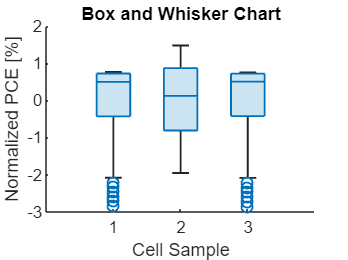

NN = table2array(N);
boxchart(NN(:,8:10))
xlabel('Cell Sample')
ylabel('Normalized PCE [%]')
title('Box and Whisker Chart')

The code for the violin graph is omitted, since it can be inferred that biased results will be obtained or that they do not resemble the conclusions obtained from the original data.

It can be concluded that for the analysis of perovskite solar cells, data normalization is not a very useful method to evaluate the separability of the electrical variables.

6. (20%) With the normalized data, apply a mathematical algorithm (data-driven like machine learning, regression, fitting, etc.) to perform automatic data categorization, classification or prediction, depending on your research problem. Provide performance measurements (mean square error, loss, accuracy, AUC, etc.) in order to evaluate how well behaves the algorithm.

Due to the difficulties exposed in the previous item regarding the problems presented when normalizing the DataFrame data, it is pertinent to clarify that the analyzes presented below are carried out with the original data.

% RMS for Jsc
Solar_Cell_Array=table2array(Solar_Cell);
RMS_Jsc_Cell1=rms(ctranspose(Solar_Cell_Array(:,2)))

RMS_Jsc_Cell1 = 25.1092

RMS_Jsc_Cell2=rms(ctranspose(Solar_Cell_Array(:,3)))

RMS_Jsc_Cell2 = 33.1698

RMS_Jsc_Cell3=rms(ctranspose(Solar_Cell_Array(:,4)))

RMS_Jsc_Cell3 = 22.0390



% RMS for Voc

RMS_Voc_Cell1=rms(ctranspose(Solar_Cell_Array(:,5)))

RMS_Voc_Cell1 = 1.1870

RMS_Voc_Cell2=rms(ctranspose(Solar_Cell_Array(:,6)))

RMS_Voc_Cell2 = 1.1260

RMS_Voc_Cell3=rms(ctranspose(Solar_Cell_Array(:,7)))

RMS_Voc_Cell3 = 1.1293


% RMS for PCE
Solar_Cell_Array=table2array(Solar_Cell);
RMS_PCE_Cell1=rms(ctranspose(Solar_Cell_Array(:,8)))

RMS_PCE_Cell1 = 16.1517

RMS_PCE_Cell2=rms(ctranspose(Solar_Cell_Array(:,9)))

RMS_PCE_Cell2 = 17.3780

RMS_PCE_Cell3=rms(ctranspose(Solar_Cell_Array(:,10)))

RMS_PCE_Cell3 = 13.8929

The RMS values show that the highest value in the 3 analyses is generated in cell 2. The value is high due to the behavior of the cell parameters as their efficiencies change. This measurement can also be useful to know which of the different photovoltaic devices can generate the highest possible efficiency.

As it could be observed in the previous analysis, the cell is the one that shows the highest value of efficiency but also its values are the ones that present the highest variance density with respect to cell 1 and 2. This means that the thickness variation in cell 2 represents a direct impact on PCE. Therefore, I can conclude that the higher the thickness of the films in this cell, the better performance it will present and the more significant will be the performance of the cells. This confirms the data found in the literature [1-3].

For the ongoing research, it is imperative to analyze the function that describes the energy efficiency (PCE) versus the variation in the thickness of the cell layers, which is described in detail below and graphs are presented to illustrate to the reader visually how it is done. These two design parameters entail for the three simulated cells.

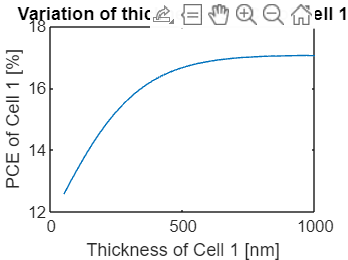

plot_cell(Thickness, PCE_Cell1, 1)% Cell 1

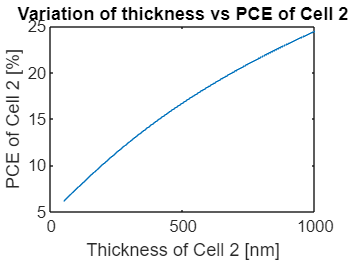


plot_cell(Thickness, PCE_Cell2, 2)% Cell 2

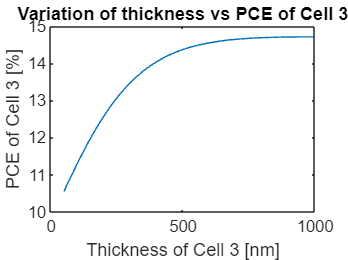


plot_cell(Thickness, PCE_Cell3, 3)% Cell 3

#### Cell 1

For the thickness vs PCE graph of cell 1, it can be seen that the energy efficiency value starts at approximately 12.5% ��when the cell thickness is 50 nm and the energy efficiency begins to describe a behavior with a negligible increase from a value of 600 nm. In this case, the thickness of 600 nm can be defined as a design parameter in which an acceptable efficiency is achieved and the use of materials is reduced, since the increase in efficiency does not represent a considerable benefit in the conversion of sunlight into energy.

#### Cell 2

The graph in cell 2 describes an ascending behavior with increasing thickness. Unlike cell 1, this structure describes an almost linear increase and it can be thought that if the range of variation for the thickness is expanded, efficiencies greater than 25% can be obtained. Furthermore, this cell is the one with the greatest increase in PCE, which generated an initial value of 6% for a thickness of 50 nm and a final energy efficiency of 24.5% with a thickness of 1000 nm. Therefore, a future analysis of this prototype with a thickness between 50 nm and 2000 nm is proposed to verify the peak PCE value.

#### Cell 3

Cell 3 presents a behavior similar to that obtained for cell 1, since the PCE value varies between 10.5% and 14.7% and begins to stabilize from 600 nm. In this case, you can also define this thickness value as a design parameter and thus avoid the use of material. This turns out to be very useful, since some materials used in the manufacture of perovskite solar cells have a high cost, such as Gold or Spiro-OMETAD.

In conclusion, the statistical analysis using the data generated through numerical simulation allows us to determine which of the designed devices have the best performance and fixed design parameters can be easily obtained, avoiding the waste of high-cost materials and preserving ultra-thin cells, a characteristic that attracts great interest from the scientific community.

## **Bibliographic References**

[1] Vivek B., Praveen K., Deepak B., Shashi K., Michał J., Radomir G., Zbigniew L. (2023). Numerical Investigation of Power Conversion Efficiency of Sustainable Perovskite Solar Cells. *Electronics*, 12, 1762. [http://dx.doi.org/10.3390/electronics12081762](http://dx.doi.org/10.3390/electronics12081762)

[2] Ouslimane, T., Et-taya, L., Elmaimouni, L., & Benami, A. (2021). Impact of absorber layer thickness, defect density, and operating temperature on the performance of MAPbI3 solar cells based on ZnO electron transporting material. *Heliyon*, *7*(3), e06379. [https://doi.org/10.1016/j.heliyon.2021.e06379](https://doi.org/10.1016/j.heliyon.2021.e06379)

[3] Vélez, J., Sepúlveda, F., Botero, M., Otalora, C., & Camacho, C. (2023). Absorber layer thickness as a new feature in statistical learning tools of Perovskite solar cells. *Journal of Applied Research and Technology*, *21,* 858–865. [https://doi.org/10.22201/ICAT.24486736E.2023.21.5.2057](https://doi.org/10.22201/ICAT.24486736E.2023.21.5.2057)

[4] Montoya, I., Cortina, H., Ruíz, M., Hechavarría, L., Sánchez, F., Courel, M., & Hu, H. (2020). Optimization of CH3NH3PbI3 perovskite solar cells: A theoretical and experimental study. *Solar Energy, *199, 198-205.

[http://dx.doi.org/10.1016/j.solener.2020.02.026](http://dx.doi.org/10.1016/j.solener.2020.02.026)

[5] Holger Hoffmann (2024). Violin Plot, MATLAB Central File Exchange. Retrieved junio 7, 2024.

[https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot](https://www.mathworks.com/matlabcentral/fileexchange/45134-violin-plot)

## Functions implemented for algorithm optimization

**Mean calculation and plotting**

function plot_means(Solar_Cell, variables, labels)
% Function to plot mean of DataFrame columns
% This function allows you to enter a dataframe, calculate the average 
% of the electrical variables and display them in bar graphs.
%
% Solar_Cell: It is the DataFrame to calculate the mean
% variables: It allows to define the columns that will be used to calculate
% the mean.
% labels: It describes the electrical variable name and the units used to
% plot

    Mean = mean(Solar_Cell);

    % Cell number
    Cells_Number = [1,2,3];

    % Iterate on the variables to be plotted
    for i = 1:length(variables)
        % Get info of current variable
        var_data = table2array(Mean(:, variables{i}));

        % Create bar plot
        figure;
        b = bar(Cells_Number, var_data);

        % Add lables
        x_label = b.XEndPoints;
        y_label = b.YEndPoints;
        labels1 = string(b.YData);
        text(x_label, y_label, labels1, 'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'bottom');

        % Add legends
        ylabel(['Mean of ', labels{i}]);
        xlabel('Cell sample');
        title(['Cell sample vs Mean of ', labels{i}]);
    end
end

**Standard deviation calculation and plotting**

function plot_standard_deviation(Solar_Cell, variables, labels)
% Function to plot the standard deviation of DataFrame columns.
% 
% This function allows you to enter a dataframe, calculate the 
% standard deviation of the electrical variables and display 
% them in bar graphs.
%
% Solar_Cell: It is the DataFrame to calculate the standard deviation.
% variables: It allows to define the columns that will be used to calculate
% the mean.
% labels: It describes the electrical variable name and the units used to
% plot.
    % Calcular la desviación estándar de las variables seleccionadas
    Cells_Number = [1,2,3];
    
    % Iterar sobre las variables a graficar
    for i = 1:length(variables)
        % Obtener los datos de la desviación estándar de la variable actual
        S = std(table2array(Solar_Cell(:, variables{i})));
        
        % Crear la gráfica de barras
        figure;
        SD = bar(Cells_Number, S);
        
        % Añadir etiquetas a las barras
        x_label = SD.XEndPoints;
        y_label = SD.YEndPoints;
        labels1 = string(SD.YData);
        text(x_label, y_label, labels1, 'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'bottom');
        
        % Añadir etiquetas y título a la gráfica
        ylabel(['Standard deviation for ', labels{i}]);
        xlabel('Cell sample');
        title(['Cell sample vs Standard deviation for ', labels{i}]);
    end
end

**Thickness Vs PCE plotting**

function plot_cell(thickness, PCE, cell_num)
% Plot thickness versus energy efficiency (PCE) 
% This function generates a graph of cell thickness 
% versus efficiency with labels and title. 
% 
% Inputs: 
% thickness: Array with the thickness variation range. 
% PCE: Array with the PCE got by simulation. 
% cell_num: Represents the number that identifies the cell to be evaluated.
% Note: Both, the thickness and the PCE must have the same dimensions.

    % Plotting efficiency vs thickness for a specific cell
    plot(thickness, PCE)
    ylabel(['PCE of Cell ' num2str(cell_num) ' [%]'])
    xlabel(['Thickness of Cell ' num2str(cell_num) ' [nm]'])
    title(['Variation of thickness vs PCE of Cell ' num2str(cell_num)])
end